# Airport network

In this live script the airport network structure is analyzed. The data has been downloaded from [Kaggle](http://kaggle.com) and they contain the description of a set of 67663 flights on a global scale, including departure and destination airports, the airline company IDs and other information which are not needed for the creation of the network.

#### Setup and data loading

clear; close all; clc
repository = "airport-network";
folders = split(pwd, filesep);
idx = find(folders == repository);
root = string(join(folders(1:idx), filesep));
addpath(genpath(root));
routes = importfile('routes.csv');

## Data exploration

disp("The data contains "+height(routes)+" entries in total")

The data contains 67663 entries in total


head(routes, 3)

ans = 3×9 table
    airline    airlineID    sourceairport    sourceairportid    destinationairport    destinationairportid    codeshare    stops    equipment
    _______    _________    _____________    _______________    __________________    ____________________    _________    _____    _________

      2B          410            AER              2965                 KZN                    2990               ""          0         CR2   
      2B          410            ASF              2966                 KZN                    2990               ""          0         CR2   
      2B          410            ASF              2966                 MRV                    2962           

### Missing data

In the table there are 4 numeric columns, ['airlineID', 'sourceairportid', 'destinationairportid', 'stops'], in which there could be NaN values due to missing data. Here we investigate how many are there and where they are located. The expected behaviour is of airlines and airports not having an ID associated to them, so we're going to check whether all the ID fields associated to those are NaN.

missing = [sum(isnan(routes.airlineID)), sum(isnan(routes.sourceairportid)), ...
           sum(isnan(routes.destinationairportid)), sum(isnan(routes.stops))];
disp("Missing elements" + newline + ...
     " airlineID: " + missing(1) + newline + ...
     " sourceairportid: " + missing(2) + newline + ...
     " destinationairportid: " + missing(3) + newline + ...
     " stops: " + missing(4))

Missing elements
 airlineID: 479
 sourceairportid: 220
 destinationairportid: 221
 stops: 0


#### airlineID

Here, for the airlines which are associated to at least one NaN, the percentage of data entries with a NaN ID are printed.

missing_airlines = unique(routes.airline(isnan(routes.airlineID)));
for i = 1:numel(missing_airlines)
    check = isnan(routes.airlineID(routes.airline == missing_airlines(i)));
    pctg = sum(check)/numel(check);
    disp(string(missing_airlines(i))+": "+num2str(pctg))
end

3H: 1
4E: 1
4W: 1
5U: 1
6L: 1
7S: 1
9D: 1
9M: 1
EB: 1
HS: 1
O4: 1
P1: 1
P2: 1
P6: 1
PB: 1
WT: 1
X4: 1
XU: 1
YJ: 1
YN: 1
ZD: 1


As expected, only some of the airports don't have an ID in this table, and that's why there are the NaN values.

#### sourceairportid

missing_source = unique(routes.sourceairport(isnan(routes.sourceairportid)));
for i = 1:numel(missing_source)
    check = isnan(routes.sourceairportid(routes.sourceairport == missing_source(i)));
    pctg = sum(check)/numel(check);
    disp(string(missing_source(i))+": "+num2str(pctg))
end

ABB: 1
AOQ: 1
BTC: 1
BUL: 1
CBS: 1
CFK: 1
CKX: 1
DEF: 1
DOB: 1
EBH: 1
EDA: 1
EKS: 1
GCH: 1
GMO: 1
HOE: 1
HYD: 1
IKE: 1
IOQ: 1
IOT: 1
IUI: 1
JAU: 1
JJA: 1
JKR: 1
JUK: 1
JUU: 1
KCK: 1
KCO: 1
KGQ: 1
KHQ: 1
KHY: 1
KHZ: 1
KQT: 1
KSE: 1
KUZ: 1
KWF: 1
KXU: 1
LFM: 1
LLB: 1
LMA: 1
MEU: 1
MLH: 1
MNS: 1
MQJ: 1
MZW: 1
NER: 1
NGK: 1
NIQ: 1
NKI: 1
NOP: 1
NSQ: 1
OGM: 1
OLL: 1
ORU: 1
ORZ: 1
OSM: 1
PBZ: 1
PHB: 1
PQM: 1
QFG: 1
QFN: 1
QJH: 1
QOQ: 1
QUV: 1
QUW: 1
RCY: 1
RKA: 1
SAE: 1
SGG: 1
SQS: 1
SRK: 1
SUK: 1
SVR: 1
SXI: 1
TBI: 1
TGK: 1
TGP: 1
THX: 1
TQA: 1
TQI: 1
TZL: 1
UGB: 1
ULZ: 1
UPK: 1
UTS: 1
WAE: 1
XEQ: 1
YNP: 1
ZBL: 1
ZGS: 1


#### destinationairportid

missing_dest = unique(routes.destinationairport(isnan(routes.destinationairportid)));
for i = 1:numel(missing_dest)
    check = isnan(routes.destinationairportid(routes.destinationairport == missing_dest(i)));
    pctg = sum(check)/numel(check);
    disp(string(missing_dest(i))+": "+num2str(pctg))
end

ABB: 1
AOQ: 1
BSS: 1
BTC: 1
BUL: 1
CBS: 1
CFK: 1
CKX: 1
DEF: 1
DOB: 1
EBH: 1
EDA: 1
EKS: 1
GCH: 1
GMO: 1
HOE: 1
HYD: 1
IKE: 1
IOQ: 1
IOT: 1
IUI: 1
JAU: 1
JJA: 1
JKR: 1
JUK: 1
JUU: 1
KCK: 1
KCO: 1
KGQ: 1
KHQ: 1
KHY: 1
KHZ: 1
KQT: 1
KSE: 1
KUZ: 1
KWF: 1
KXU: 1
LFM: 1
LLB: 1
LMA: 1
MEU: 1
MLH: 1
MNS: 1
MQJ: 1
MTE: 1
MZW: 1
NER: 1
NGK: 1
NIQ: 1
NKI: 1
NOP: 1
NSQ: 1
OGM: 1
OLL: 1
ORU: 1
ORZ: 1
OSM: 1
PBZ: 1
PHB: 1
PQM: 1
QFG: 1
QFN: 1
QFX: 1
QJH: 1
QOQ: 1
QUV: 1
QUW: 1
RCY: 1
RKA: 1
SAE: 1
SGG: 1
SQS: 1
SRK: 1
SUK: 1
SVR: 1
SXI: 1
TBI: 1
TGK: 1
TGP: 1
THX: 1
TQA: 1
TQI: 1
TZL: 1
UGB: 1
ULZ: 1
UPK: 1
UTS: 1
WAE: 1
XEQ: 1
YNP: 1
ZBL: 1
ZGS: 1


The total number of airports without ID is here computed, by comparing source and destination lists:

missing_airportid = unique([missing_source;missing_dest]);
disp("Airports without ID: "+numel(missing_airportid))

Airports without ID: 92


### Available data

Note: when calling unique(), NaN are counted as different values, so the number of total airlineID has to be corrected removing all the NaNs. The difference between the number of airlines and airlineIDs should be the number of elements inside the missing_airlines vector.

n_airline = numel(unique(routes.airline));
n_airlineID = numel(unique(routes.airlineID)) - missing(1);
disp("There are "+int2str(n_airline)+" airlines, "+int2str(n_airlineID)+" airline IDs and "+int2str(numel(missing_airlines))+" missing IDs.")

There are 568 airlines, 547 airline IDs and 21 missing IDs.


Similarly, this should hold true for airport names and codes.

n_airport = numel(unique([routes.sourceairport;routes.destinationairport]));
n_airportID = numel(unique([routes.sourceairportid;routes.destinationairportid])) - missing(2) - missing(3);
disp("There are "+int2str(n_airport)+" airports, "+int2str(n_airportID)+" airport IDs and "+int2str(numel(missing_airportid))+" missing IDs.")

There are 3425 airports, 3333 airport IDs and 92 missing IDs.


## Network creation

edges = [routes.sourceairport routes.destinationairport];
weights = ones(height(routes),1);
EdgeTable = table(string(edges), weights,'VariableNames',{'EndNodes','Weight'});
head(EdgeTable)

ans = 8×2 table
       EndNodes       Weight
    ______________    ______

    "AER"    "KZN"      1   
    "ASF"    "KZN"      1   
    "ASF"    "MRV"      1   
    "CEK"    "KZN"      1   
    "CEK"    "OVB"      1   
    "DME"    "KZN"      1   
    "DME"    "NBC"      1   
    "DME"    "TGK"      1   


G = digraph(EdgeTable);
disp("This network contains "+int2str(numel(G.Nodes))+" nodes and "+int2str(numel(G.Edges(:,1)))+" edges.")

This network contains 3425 nodes and 67663 edges.


Some edges though are repeated, so here we discard the repetitions adding weight to the corresponding edge.

EdgeTable = unique(EdgeTable);
for e = 1:height(EdgeTable)
    EdgeTable.Weight(e) = sum((EdgeTable.EndNodes(e,1) == string(edges(:,1))) & (EdgeTable.EndNodes(e,2) == string(edges(:,2))));
end
disp("The sum of weights is still " + sum(EdgeTable.Weight))

The sum of weights is still 67663


G = digraph(EdgeTable);

fig.graph = figure('Name','Network graph','WindowState','maximized');
fig.plot = plot(G,'Layout','force');

fig = struct with fields:
    graph: [1×1 Figure]
     plot: [1×1 GraphPlot]


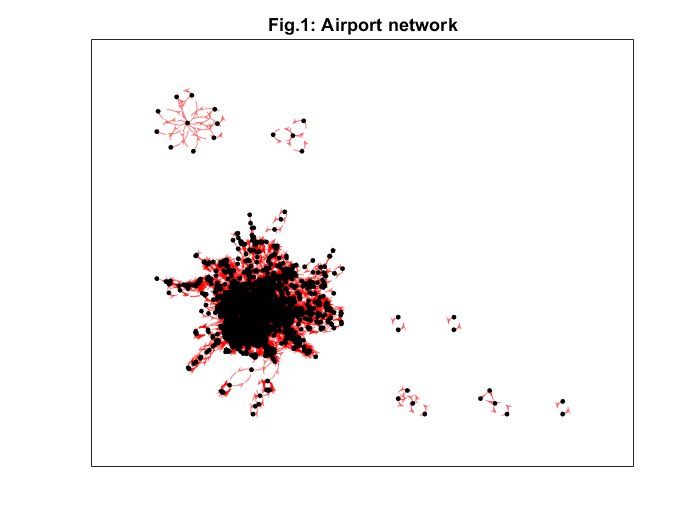

fig.plot.NodeColor = 'k';
fig.plot.EdgeColor = 'r';
fig.plot.LineStyle = '--';
title('Fig.1: Airport network');